clear all
figure

data = readtable("Optimisation7.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph     RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2 
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    _________    __________________    __________________    _________________    ______________________    _______<


resultTab1 = data{:, :};
resultTab1 = resultTab1(:,[11,12,13])

resultTab1 =     0.4619   -2.3979    1.6216
   -0.1830   -2.3979    2.5904
    0.0546   -2.3979    1.7886
    1.2713   -2.3026    1.1980
    0.0055   -2.3979    2.3444
   -0.3183   -2.3979    2.6093
    1.2074   -2.3979    1.1613
   -0.4452   -2.3979    2.1572
   -0.4966   -2.3979    1.8920
    0.0280   -2.3979    1.6566



resultTab1(:,1) = exp(-resultTab1(:,1))

resultTab1 =     0.6301   -2.3979    1.6216
    1.2008   -2.3979    2.5904
    0.9468   -2.3979    1.7886
    0.2805   -2.3026    1.1980
    0.9946   -2.3979    2.3444
    1.3749   -2.3979    2.6093
    0.2990   -2.3979    1.1613
    1.5608   -2.3979    2.1572
    1.6431   -2.3979    1.8920
    0.9724   -2.3979    1.6566


resultTab1(:,2) = exp(-resultTab1(:,2))

resultTab1 =     0.6301   11.0000    1.6216
    1.2008   11.0000    2.5904
    0.9468   11.0000    1.7886
    0.2805   10.0000    1.1980
    0.9946   11.0000    2.3444
    1.3749   11.0000    2.6093
    0.2990   11.0000    1.1613
    1.5608   11.0000    2.1572
    1.6431   11.0000    1.8920
    0.9724   11.0000    1.6566


resultTab1(:,3) = -exp(resultTab1(:,3))

resultTab1 =     0.6301   11.0000   -5.0611
    1.2008   11.0000  -13.3357
    0.9468   11.0000   -5.9808
    0.2805   10.0000   -3.3135
    0.9946   11.0000  -10.4272
    1.3749   11.0000  -13.5894
    0.2990   11.0000   -3.1941
    1.5608   11.0000   -8.6472
    1.6431   11.0000   -6.6327
    0.9724   11.0000   -5.2417



utopiaPoint1 = [max(resultTab1(:,1)), max(resultTab1(:,2)), max(resultTab1(:,3))]

utopiaPoint1 =     1.6555   11.0000   -2.1769


antiutopiaPointTemp = [min(resultTab1(:,1)), min(resultTab1(:,2)), min(resultTab1(:,3))]

antiutopiaPointTemp =     0.2768    9.0000  -14.5601



antiutopiaPointCorr = 0.01.*(utopiaPoint1-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0138    0.0200    0.1238


antiutopiaPoint1 = antiutopiaPointTemp - antiutopiaPointCorr 

antiutopiaPoint1 =     0.2630    8.9800  -14.6839



data = readtable("Optimisation8.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph    RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018    Dist2
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    ________    __________________    __________________    _________________    ______________________    _____


resultTab2 = data{:, :};
resultTab2 = resultTab2(:,[11,12,13])

resultTab2 =     0.0266   -2.3026    2.1527
    0.0313   -2.3979    2.2657
    0.2581   -2.3979    1.6592
   -0.2265   -2.3979    2.1533
    0.5864   -2.3979    1.5498
   -0.1757   -2.1972    2.6599
    0.6036   -2.3979    2.0025
    0.3001   -2.3026    1.9519
    0.4513   -2.3979    1.5138
   -0.2924   -2.3979    2.0343



resultTab2(:,1) = exp(-resultTab2(:,1))

resultTab2 =     0.9737   -2.3026    2.1527
    0.9692   -2.3979    2.2657
    0.7725   -2.3979    1.6592
    1.2542   -2.3979    2.1533
    0.5563   -2.3979    1.5498
    1.1921   -2.1972    2.6599
    0.5468   -2.3979    2.0025
    0.7408   -2.3026    1.9519
    0.6368   -2.3979    1.5138
    1.3397   -2.3979    2.0343


resultTab2(:,2) = exp(-resultTab2(:,2))

resultTab2 =     0.9737   10.0000    2.1527
    0.9692   11.0000    2.2657
    0.7725   11.0000    1.6592
    1.2542   11.0000    2.1533
    0.5563   11.0000    1.5498
    1.1921    9.0000    2.6599
    0.5468   11.0000    2.0025
    0.7408   10.0000    1.9519
    0.6368   11.0000    1.5138
    1.3397   11.0000    2.0343


resultTab2(:,3) = -exp(resultTab2(:,3))

resultTab2 =     0.9737   10.0000   -8.6083
    0.9692   11.0000   -9.6379
    0.7725   11.0000   -5.2552
    1.2542   11.0000   -8.6130
    0.5563   11.0000   -4.7104
    1.1921    9.0000  -14.2951
    0.5468   11.0000   -7.4073
    0.7408   10.0000   -7.0423
    0.6368   11.0000   -4.5437
    1.3397   11.0000   -7.6472



utopiaPoint2 = [max(resultTab2(:,1)), max(resultTab2(:,2)), max(resultTab2(:,3))]

utopiaPoint2 =     1.4831   11.0000   -2.1565


antiutopiaPointTemp = [min(resultTab2(:,1)), min(resultTab2(:,2)), min(resultTab2(:,3))]

antiutopiaPointTemp =     0.1660    9.0000  -14.2951



antiutopiaPointCorr = 0.01.*(utopiaPoint2-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0132    0.0200    0.1214


antiutopiaPoint2 = antiutopiaPointTemp - antiutopiaPointCorr 

antiutopiaPoint2 =     0.1528    8.9800  -14.4165



data = readtable("Optimisation9.xlsx")

data = 50×16 table
    GradTime    InitalOM    FinalOM    Temp    IsoHoldTime    InjVol    FlowRate    Column    OMPhase    Ph     RsCrit2     Maximisepeaknumber    Minimisemethodtime    CombinedFunction1    WeightRespcmtmdHPLC018     Dist2 
    ________    ________    _______    ____    ___________    ______    ________    ______    _______    __    _________    __________________    __________________    _________________    ______________________    _______<


resultTab3 = data{:, :};
resultTab3 = resultTab3(:,[11,12,13])

resultTab3 =     0.6015   -2.3979    1.5096
    1.0731   -2.3979    2.0303
   -0.0503   -2.3979    1.6280
   -0.3661   -2.3979    1.7432
    0.3320   -2.3026    2.0901
   -0.1753   -2.3979    2.6105
    0.1729   -2.3026    2.1625
   -0.3716   -2.3979    2.3225
   -0.3910   -2.3979    2.0774
   -0.4569   -2.3979    1.8207



resultTab3(:,1) = exp(-resultTab3(:,1))

resultTab3 =     0.5480   -2.3979    1.5096
    0.3419   -2.3979    2.0303
    1.0516   -2.3979    1.6280
    1.4421   -2.3979    1.7432
    0.7175   -2.3026    2.0901
    1.1916   -2.3979    2.6105
    0.8413   -2.3026    2.1625
    1.4501   -2.3979    2.3225
    1.4784   -2.3979    2.0774
    1.5792   -2.3979    1.8207


resultTab3(:,2) = exp(-resultTab3(:,2))

resultTab3 =     0.5480   11.0000    1.5096
    0.3419   11.0000    2.0303
    1.0516   11.0000    1.6280
    1.4421   11.0000    1.7432
    0.7175   10.0000    2.0901
    1.1916   11.0000    2.6105
    0.8413   10.0000    2.1625
    1.4501   11.0000    2.3225
    1.4784   11.0000    2.0774
    1.5792   11.0000    1.8207


resultTab3(:,3) = -exp(resultTab3(:,3))

resultTab3 =     0.5480   11.0000   -4.5249
    0.3419   11.0000   -7.6164
    1.0516   11.0000   -5.0939
    1.4421   11.0000   -5.7157
    0.7175   10.0000   -8.0857
    1.1916   11.0000  -13.6064
    0.8413   10.0000   -8.6928
    1.4501   11.0000  -10.2008
    1.4784   11.0000   -7.9837
    1.5792   11.0000   -6.1760



utopiaPoint3 = [max(resultTab3(:,1)), max(resultTab3(:,2)), max(resultTab3(:,3))]

utopiaPoint3 =     1.5792   11.0000   -2.3674


antiutopiaPointTemp = [min(resultTab3(:,1)), min(resultTab3(:,2)), min(resultTab3(:,3))]

antiutopiaPointTemp =     0.1214    9.0000  -13.6064



antiutopiaPointCorr = 0.01.*(utopiaPoint3-antiutopiaPointTemp)

antiutopiaPointCorr =     0.0146    0.0200    0.1124


antiutopiaPoint3 = antiutopiaPointTemp - antiutopiaPointCorr

antiutopiaPoint3 =     0.1068    8.9800  -13.7187




utopiaPoint = max([utopiaPoint1; utopiaPoint2; utopiaPoint3])

utopiaPoint =     1.6555   11.0000   -2.1565


antiutopiaPoint = min([antiutopiaPoint1;antiutopiaPoint2;antiutopiaPoint3])

antiutopiaPoint =     0.1068    8.9800  -14.6839


%Optimisation 7
subplot(1,3,1)

paretoF = paretoFront([resultTab1(:,1) resultTab1(:,2) resultTab1(:,3)])

paretoF =     0.5444   11.0000   -3.0083
    1.0076   11.0000   -3.7863
    1.3994   11.0000   -4.8479
    1.6555   11.0000   -5.5672
    0.7478   10.0000   -2.4654
    0.2768   10.0000   -2.1769
    1.5849   11.0000   -5.1806
    0.7392   11.0000   -3.5598
    0.9732   11.0000   -3.6535
    1.6160   11.0000   -5.3655



scatter3(resultTab1(:,1), resultTab1(:,2), resultTab1(:,3), "bo", "filled")

hold on
scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
hold off

allHV = [];
for x = 7:length(resultTab1(:,1))

    paretoF = paretoFront([resultTab1(1:x,1) resultTab1(1:x,2) resultTab1(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.4548
   -0.6113
   -0.7093
   -0.7227
   -0.7232
   -0.7235
   -0.7426
   -0.7434
   -0.7434
   -0.7571


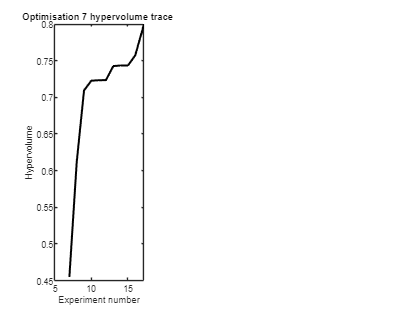


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 7 hypervolume trace ")
ylim([0.45 0.8])

%Optimisation 8
subplot(1,3,2)

paretoF = paretoFront([resultTab2(:,1) resultTab2(:,2) resultTab2(:,3)])

paretoF =     0.3013   11.0000   -2.9262
    1.3131   11.0000   -5.2221
    1.1686    9.0000   -2.9595
    0.6652   11.0000   -3.4579
    0.7985   11.0000   -3.5610
    0.7794    9.0000   -2.1565
    1.0497    9.0000   -2.2104
    0.8485   10.0000   -2.4871
    0.9151   11.0000   -3.9975
    0.9850   11.0000   -4.4760



scatter3(resultTab2(:,1), resultTab2(:,2), resultTab2(:,3), "bo", "filled")

hold on
scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
hold off

allHV = [];
for x = 7:length(resultTab2(:,1))

    paretoF = paretoFront([resultTab2(1:x,1) resultTab2(1:x,2) resultTab2(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.4862
   -0.4873
   -0.4927
   -0.5484
   -0.5484
   -0.5771
   -0.5771
   -0.6118
   -0.6212
   -0.6237


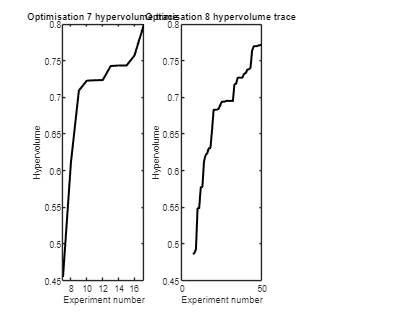


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 8 hypervolume trace ")
ylim([0.45 0.8])

%Optimisation 9
subplot(1,3,3)

paretoF = paretoFront([resultTab3(:,1) resultTab3(:,2) resultTab3(:,3)])

paretoF =     1.0516   11.0000   -5.0939
    1.5792   11.0000   -6.1760
    0.9813   11.0000   -4.4782
    1.1565    9.0000   -2.9292
    0.7459   10.0000   -3.0867
    1.4854   11.0000   -5.5580
    0.4058   11.0000   -2.5742
    0.5910   10.0000   -2.3674
    0.5902   11.0000   -3.3285
    1.2762   11.0000   -5.1425



scatter3(resultTab3(:,1), resultTab3(:,2), resultTab3(:,3), "bo", "filled")

hold on
scatter3(paretoF(:,1), paretoF(:,2), paretoF(:,3), "ro")
scatter3(utopiaPoint(1), utopiaPoint(2), utopiaPoint(3), "go", "filled")
scatter3(antiutopiaPoint(1), antiutopiaPoint(2), antiutopiaPoint(3), "ko", "filled")
hold off

allHV = [];
for x = 7:length(resultTab3(:,1))

    paretoF = paretoFront([resultTab3(1:x,1) resultTab3(1:x,2) resultTab3(1:x,3)]);
    allHV = [allHV; hypervolume([paretoF(:,1), paretoF(:,2), paretoF(:,3)], antiutopiaPoint, utopiaPoint, 1000000)];

end

allMinHV = minResp(-allHV)

allMinHV =    -0.6600
   -0.6617
   -0.6726
   -0.7205
   -0.7351
   -0.7426
   -0.7427
   -0.7509
   -0.7519
   -0.7519


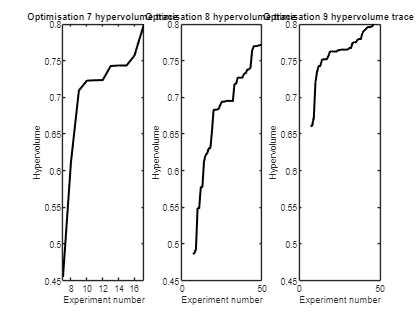


plot(7:50, -allMinHV, "black", "LineWidth", 2)

xlabel("Experiment number")
ylabel("Hypervolume")

title("Optimisation 9 hypervolume trace ")
ylim([0.45 0.8])